clc
clear
imaqreset
close all;


webcam_list = webcamlist

webcam_list = 4×1 cell array
    {'Microsoft® LifeCam Cinema(TM)'}
    {'FaceTime HD Camera (Built-in)'}
    {'Snap Camera'                  }
    {'iPhone (115) Camera'          }


imaqhwinfo

ans = struct with fields:
    InstalledAdaptors: {'macvideo'}
        MATLABVersion: '9.13 (R2022b)'
          ToolboxName: 'Image Acquisition Toolbox'
       ToolboxVersion: '6.7 (R2022b)'


% imaqhwinfo('macvideo',2)

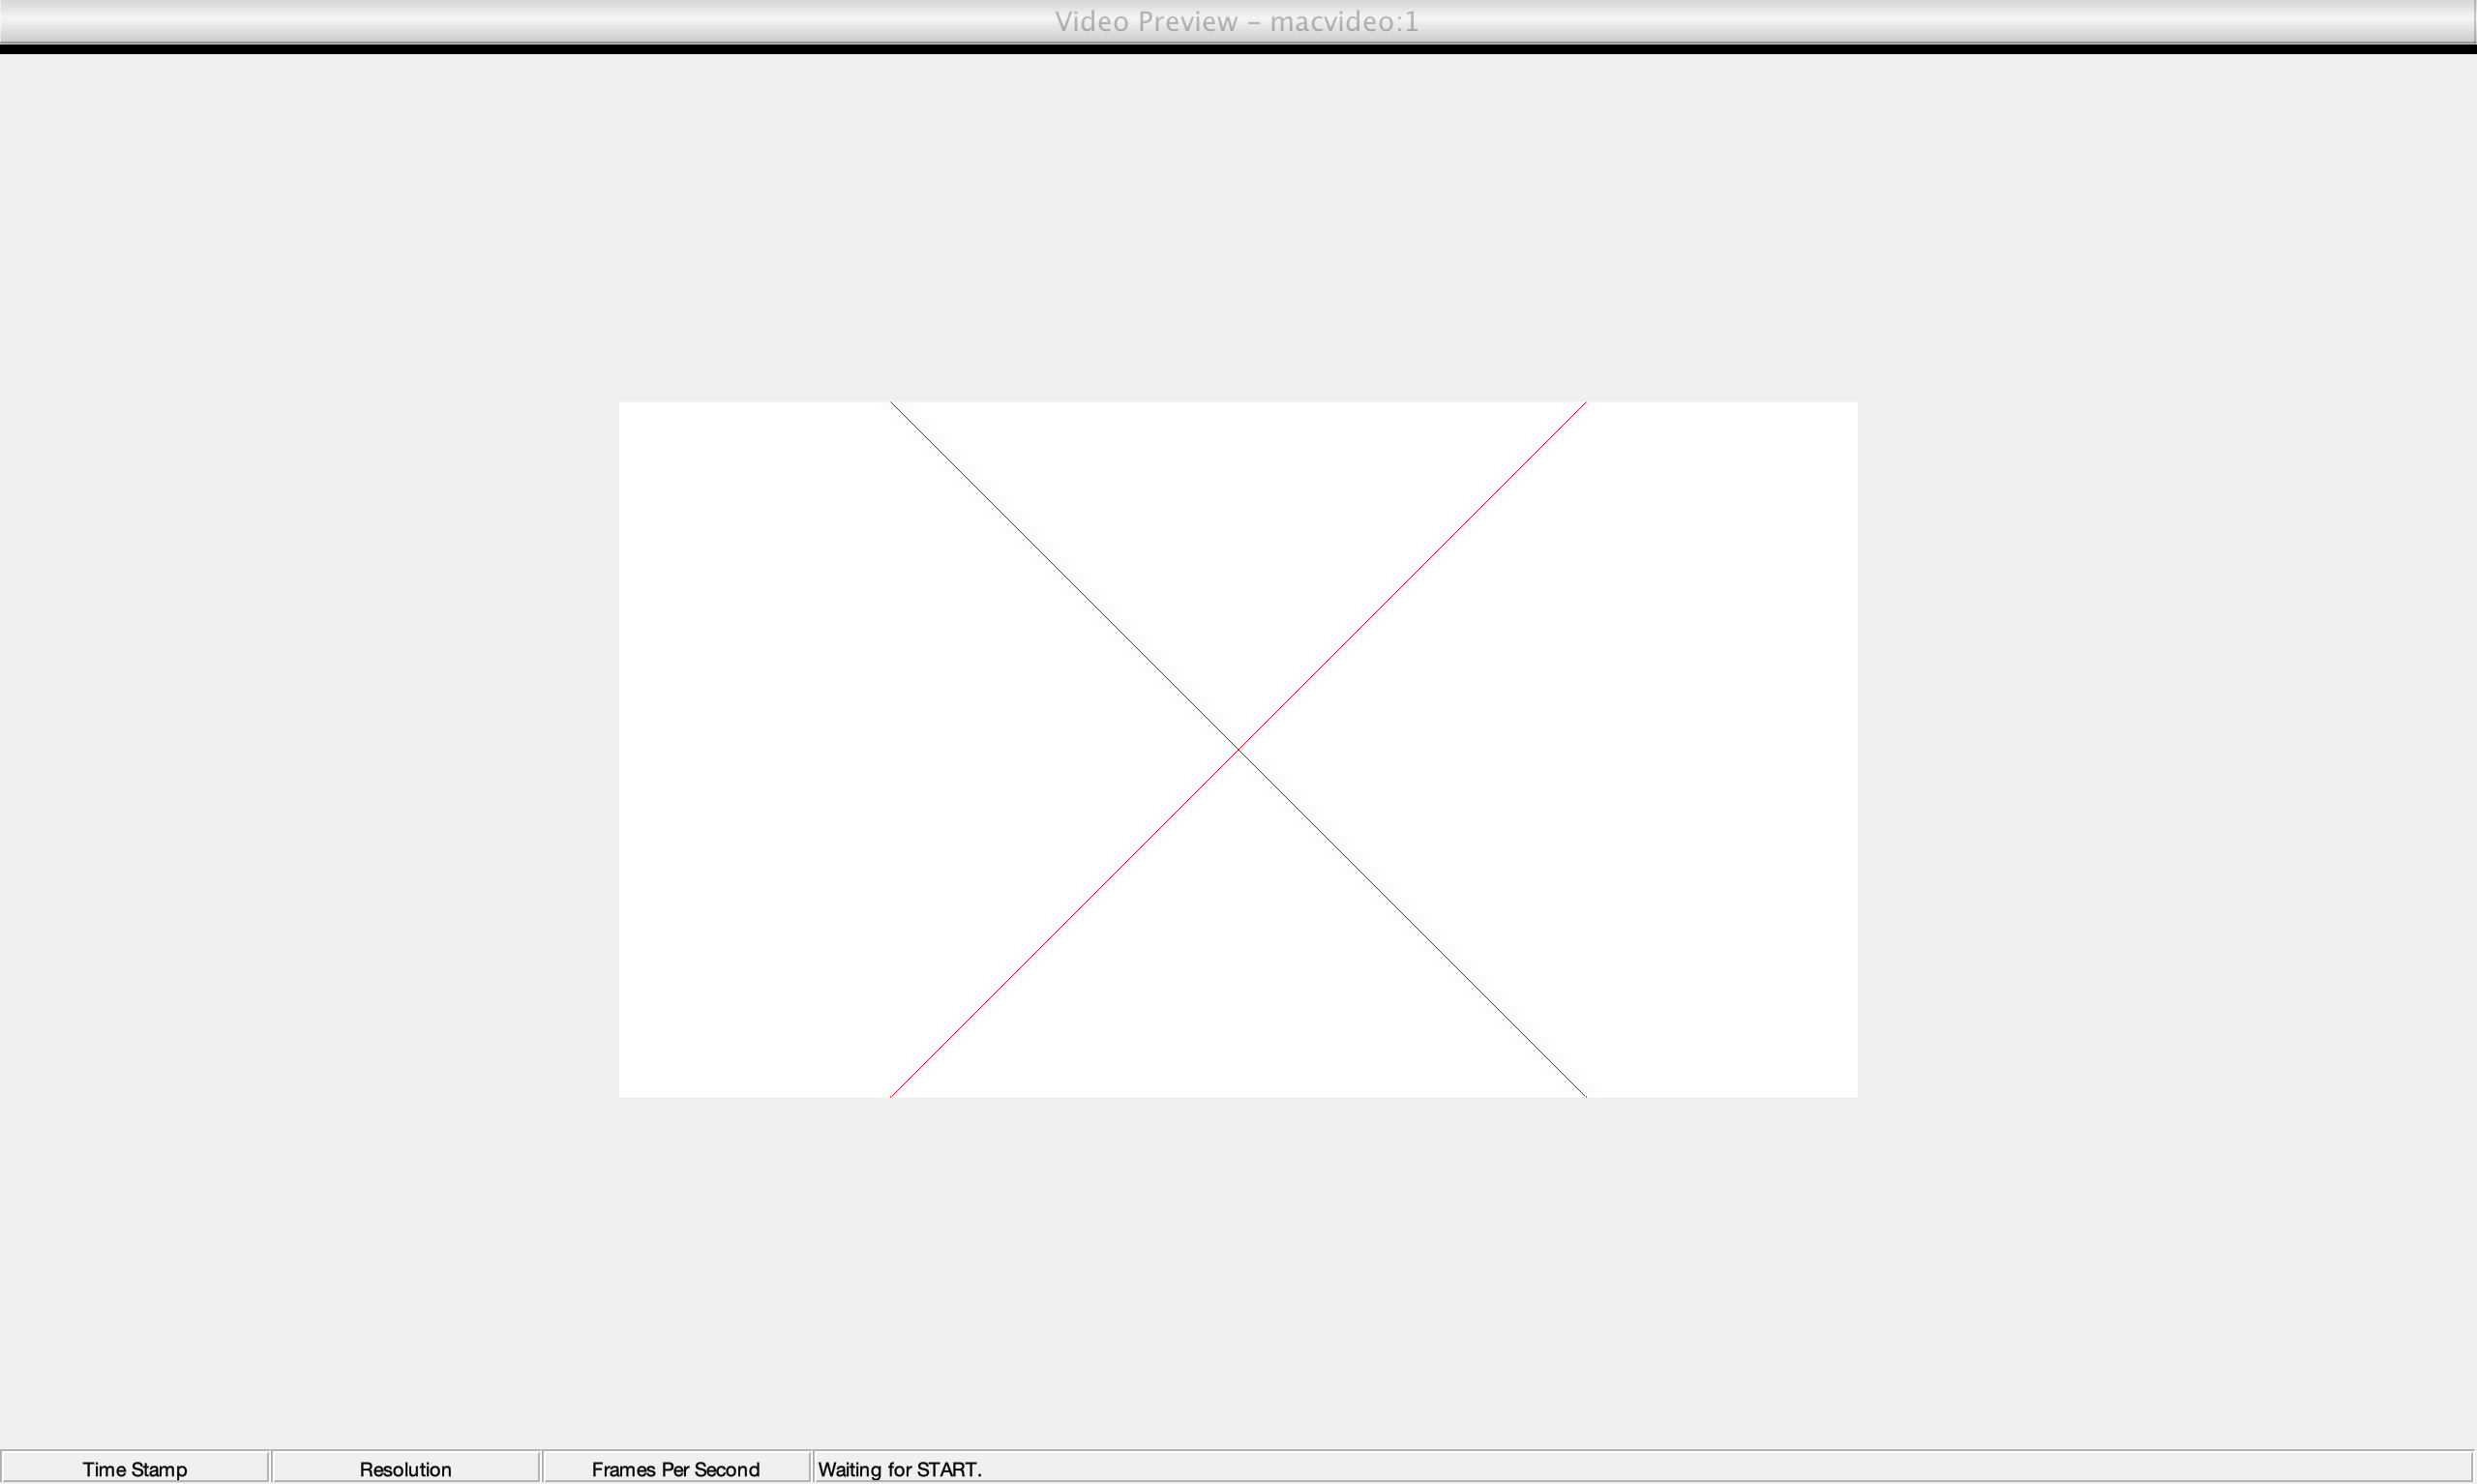

vid = videoinput('macvideo',1);

start(vid);
% data = getdata(vid,1)
% imshow(data);
preview(vid);

closepreview(vid);
stop(vid);


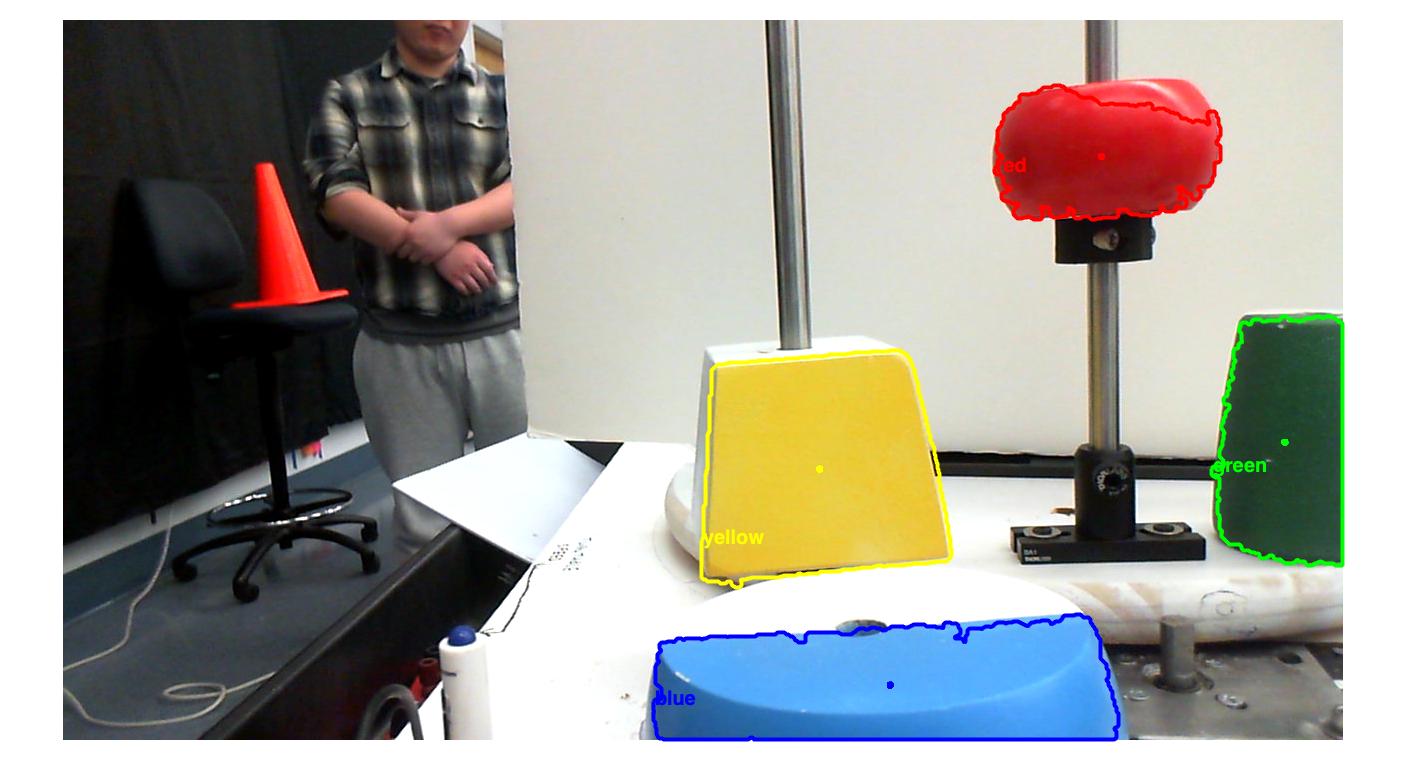

% Set video input object properties for this application.
vid.TriggerRepeat = Inf;
vid.FrameGrabInterval = 10;

% Set value of a video source object property.
vid_src = getselectedsource(vid);
vid_src.Tag = 'motion detection setup';

% Create a figure window.
close all;

figure() 
set(gcf,'Visible','on')

% Start acquiring frames.
start(vid);
pause(1);
% 
show = 1;
while show == 1
    if vid.FramesAvailable > 0
        data = getdata(vid,1); 
        img = ycbcr2rgb(data);
        imshow(img);
        hold on
        hsv_img = rgb2hsv(img);
        lower_red = [170,150,100];
        upper_red = [255,255,255];
        red_mask = mask_img(hsv_img,lower_red,upper_red);
        lower_yellow = [20,100,100];
        upper_yellow = [80,255,255];
        yellow_mask = mask_img(hsv_img,lower_yellow,upper_yellow);
        lower_green = [80,80,50];
        upper_green = [150,180,150];
        green_mask = mask_img(hsv_img,lower_green,upper_green);
        lower_blue = [100,150,100];
        upper_blue = [150,255,255];
        blue_mask = mask_img(hsv_img,lower_blue,upper_blue);

        
        if sum(sum(red_mask)) > 500      
            [largest_red,cr] = smooth_image(red_mask);
            [br, hr] = find_contour(largest_red,'red');
            plot(br(:,2), br(:,1), 'r', 'LineWidth',4);
            plot(cr(1),cr(2),'r.','MarkerSize',20);
            set(hr,'color','r','FontSize',20,'FontWeight','bold');
        end
        if sum(sum(yellow_mask)) > 500
            [largest_yellow,cy] = smooth_image(yellow_mask);
            [by, hy] = find_contour(largest_yellow,'yellow');
            plot(by(:,2), by(:,1), 'y', 'LineWidth',4);
            plot(cy(1),cy(2),'y.','MarkerSize',20);
            set(hy,'color','y','FontSize',20,'FontWeight','bold');
        end
        if sum(sum(green_mask)) > 500
            [largest_green, cg] = smooth_image(green_mask);
            [bg, hg] = find_contour(largest_green,'green');
            plot(cg(1),cg(2),'g.','MarkerSize',20);
             plot(bg(:,2), bg(:,1), 'g', 'LineWidth',4);
            set(hg,'color','g','FontSize',20,'FontWeight','bold');
        end
        if sum(sum(blue_mask)) > 500
            [largest_blue,cb] = smooth_image(blue_mask);
            [bb, hb] = find_contour(largest_blue,'blue');
             plot(bb(:,2), bb(:,1), 'b', 'LineWidth',4);
             plot(cb(1),cb(2),'b.','MarkerSize',20);
            set(hb,'color','b','FontSize',20,'FontWeight','bold');
        end
    else
        hold on
   
    end
    drawnow     % update figure window
    hold off
end

disp('ended')

stop(vid)


delete(vid)
clear
close(gcf)



function [boundary, h] = find_contour(area_img,txt)
    B = bwboundaries(area_img);
    boundary = B{1};
    rndRow = length(boundary);
    col = boundary(rndRow,2);
    row = boundary(rndRow,1);
    h = text(col+1, row-1,txt);
end

function mask = mask_img(hsv_img,lower,upper)
    lower = lower/256;
    upper = upper/256;
    h = hsv_img(:,:,1);
    s = hsv_img(:,:,2);
    v = hsv_img(:,:,3);
    h_mask = h >= lower(1) & h <= upper(1);
    s_mask = s >= lower(2) & s <= upper(2);
    v_mask = v >= lower(3) & v <= upper(3);
    mask = h_mask & s_mask & v_mask;
end

function [largest_area,centroid] = smooth_image(mask)
    %dilation
    se = strel('disk',5);
    smooth = imdilate(mask,se);
    im_fill = imfill(smooth, 'holes');

    % remove parts that are smaller than 500 pixels
    filtered = bwareaopen(im_fill,500);
%     imshow(filtered);
    % find largest area
    s = regionprops(filtered, 'Area', 'PixelList','Centroid');
    [~,idx] = max([s.Area]);
    Indices = s(idx).PixelList;
    % creates a blank binary image of the same size of image
    largest_area = false(size(filtered));
    
    for i = 1:length(Indices)
        largest_area(Indices(i,2),Indices(i,1)) = 1;
    end
    centroid = s(idx).Centroid;
    
    
end